load('/Users/torwager/Dropbox (Dartmouth College)/grants/a_IN_PREP/2021_Lindquist_Wager_HCP_basisfunctions/f2_Code_and_data/PainGen_hrf_grant_pilot_data_materials/data_for_tor.mat')
load paingen_model_results


load BFs_for_sims

wh_t = SPLINE.wh_t;
t = BF.time_in_sec;


bf = BF.spline;

n_bf = size(bf, 2);


% x = z; 
% x(2:6) = normpdf([-2 -1 0 1 2], 0, 1);



% Set up some stuff
colors = {[.3 .8 .4] [.3 .4 .8]};

z = zeros(1, n_bf)';

fit_canonical = @(y) pinv([BF.spm(:, 1) ones(size(BF.spm(:, 1), 1), 1)]) * y; % generates b

fit_spm3 = @(y) pinv([BF.spm ones(size(BF.spm, 1), 1)]) * y; % generates b


Case A. Old and younger participants have an equivalent neural response but a different HRF. This results in a reduced estimated neural activation amplitude when fitting the canonical HRF. The SPM-3 basis set is often thought to account for differences in shape and delay, but it is insufficiently flexible here and does not correct this bias.

% generate HRFs

h = z;  h(2:7) = [.1 1 .9 .5 .3 .1];

hrf_young = bf * h;
hrf_young = hrf_young ./ sum(hrf_young);  % equal area under the curve

h = z;  h(2:9) = [.1 .8 .7 .6 .4 .2 .1 .05];

hrf_older = bf * h;
hrf_older = hrf_older ./ sum(hrf_older);  % equal area under the curve

% Fit the models

by = fit_canonical(hrf_young)
bo = fit_canonical(hrf_older)

bspm3y = fit_spm3(hrf_young)
bspm3o = fit_spm3(hrf_older)


% FIT

create_figure('hrf'); 
plot(t, hrf_young, 'LineWidth', 3, 'Color', colors{1})
plot(t, hrf_older, 'LineWidth', 3, 'Color', colors{2})
xlabel('Time in sec')

ax2 = gca;
set(ax2, 'Position', [.33 .11 .45 .815]);
set(ax2, 'FontSize', 22, 'YColor', 'none', 'XLim', [0 20]);
title('HRF')
legend({'Young' 'Older'})

ax1 = axes('Position', [.13 .11 .15 .815]);
set(ax1, 'FontSize', 22, 'YLim', [0 2]); hold on; axis off
bh = bar(1, 1, 'FaceColor', colors{1});
bh2 = bar(2, 1, 'FaceColor', colors{2});
title('Neural')

ax3 = axes('Position', [.8 .11 .15 .815]);
set(ax3, 'FontSize', 22, 'YLim', [0 1]); hold on; axis off
bh = bar(1, by(1), 'FaceColor', colors{1});
bh2 = bar(2, bo(1), 'FaceColor', colors{2});
title('Amplitude')

%hold on; plot(t, BF.spm(:, 1) ./ max(BF.spm(:, 1)))


## Show how SPM3 doesn't work

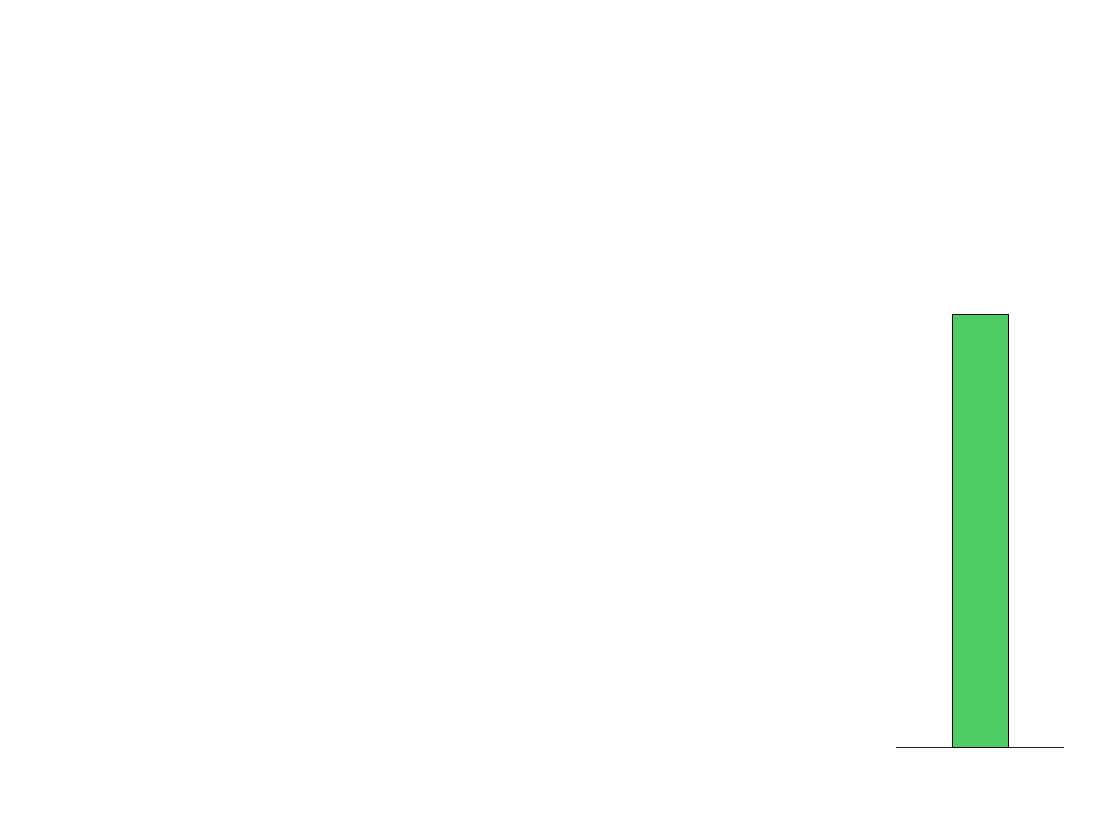

Unrecognized function or variable 'bbspm3o'.

create_figure('bf'); 
plot(t, BF.spm, 'LineWidth', 3); set(gca, 'FontSize', 22, 'XLim', [0 20], 'YColor', 'none'); 
axis tight

create_figure('hrf'); 
axis off
ax3 = axes('Position', [.8 .11 .15 .815]);
set(ax3, 'FontSize', 22, 'YLim', [0 1]); hold on; axis off
bh = bar(1, bspm3y(1), 'FaceColor', colors{1});
bh2 = bar(2, bspm3o(1), 'FaceColor', colors{2});
title('Amplitude')



Case B: A sustained emotional response in young participants is estimated as a deactivation.

% neural response functions

xz = zeros(size(bf, 1), 1);  % at TR

xshort = xz; xshort(1:3) = 1;
xlong = xz; xlong([1:3 8:4:22]) = 1;

% generate IRFs

irf_short = conv(xshort, BF.hrf(:, 1));
irf_long = conv(xlong, BF.hrf(:, 1));

irf_short = irf_short(1:length(BF.time_in_sec));
irf_long = irf_long(1:length(BF.time_in_sec));

figure; hold on
plot(t, irf_short)
plot(t, irf_long)

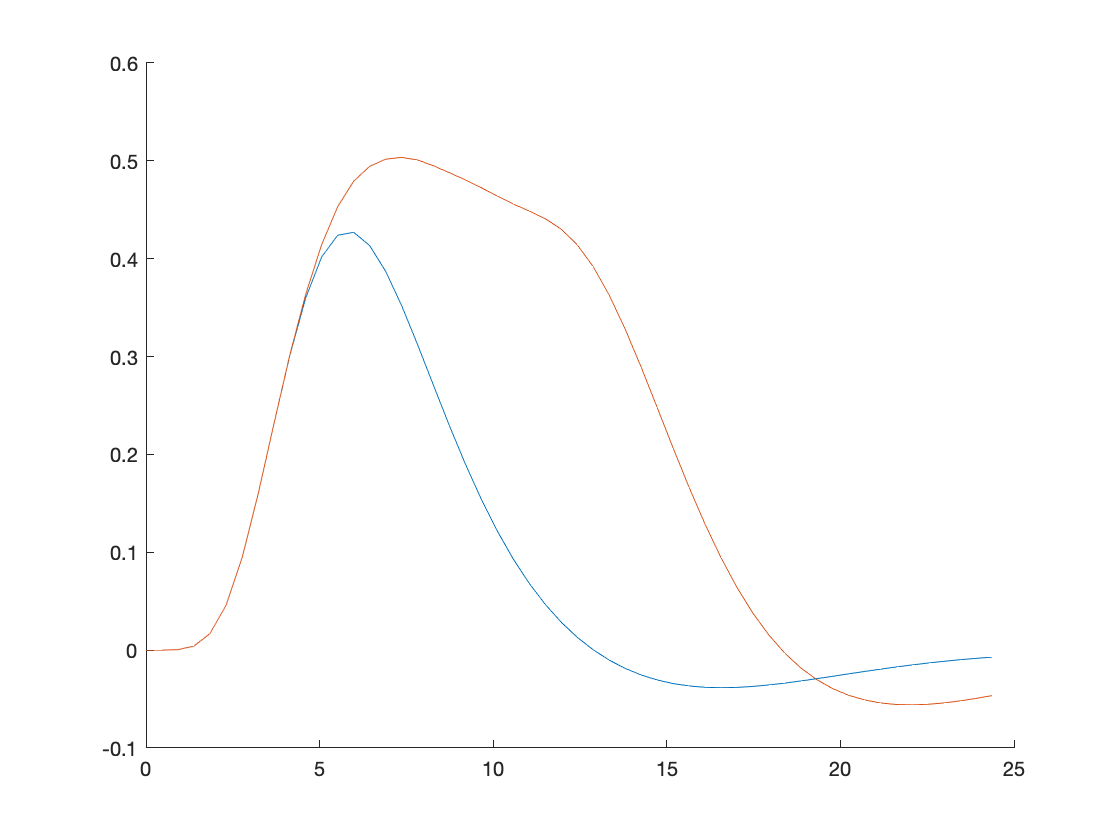


% Fit the models

by = fit_canonical(irf_short)
bo = fit_canonical(irf_long)


bspm3y = fit_spm3(irf_short)
bspm3o = fit_spm3(irf_long)



by =     4.2354
    0.0051


% FIT

bo =     3.5207
    0.1359



create_figure('hrf'); 

bspm3y =     4.2993
   -3.5251
   -0.0188
   -0.0000


lh = plot(t, irf_short, 'LineWidth', 3, 'Color', colors{1})

bspm3o =     4.0799
   -9.8261
   -4.9182
    0.0907


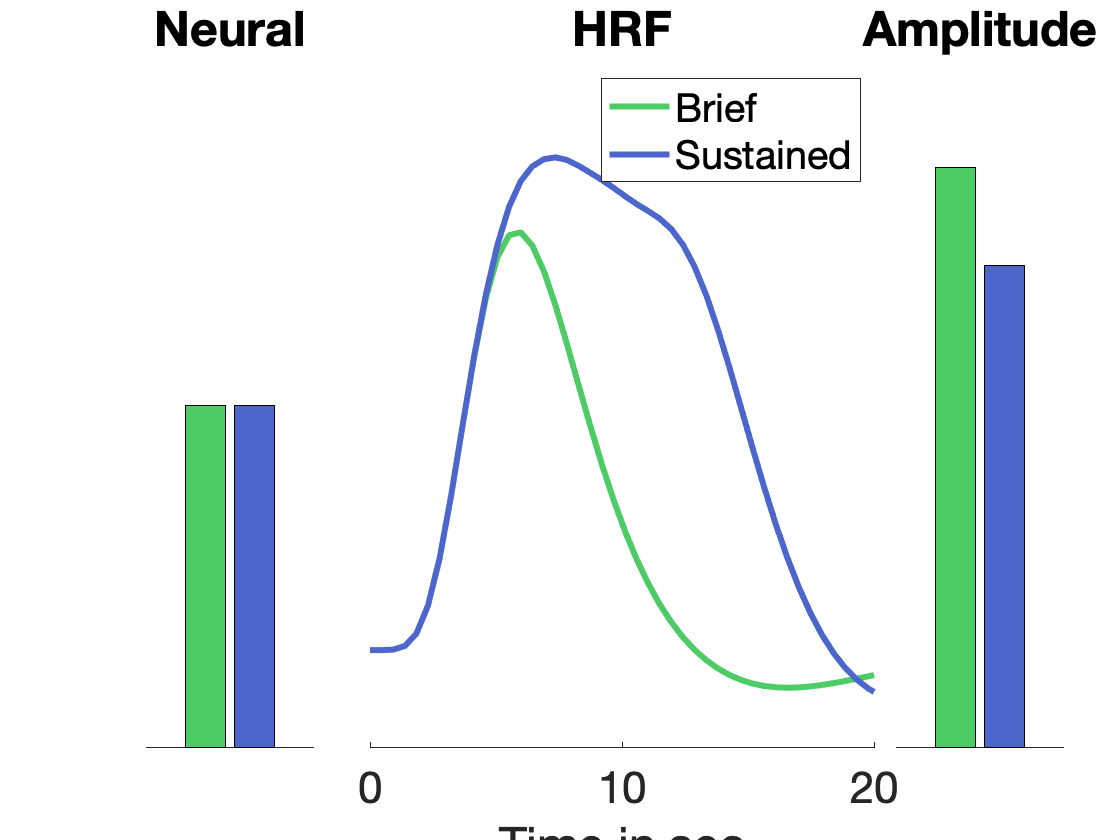

lh(2) = plot(t, irf_long, 'LineWidth', 3, 'Color', colors{2})
xlabel('Time in sec')

ax2 = gca;
set(ax2, 'Position', [.33 .11 .45 .815]);
set(ax2, 'FontSize', 22, 'YColor', 'none', 'XLim', [0 20]);
title('HRF')

hh = drawbox(0, 3, -.05, .05, colors{1});
hh2 = drawbox(0, 20 .* BF.TR, -.1, .05, colors{2});
legend(lh, {'Brief' 'Sustained'})

ax3 = axes('Position', [.8 .11 .15 .815]);
set(ax3, 'FontSize', 22); hold on; axis off
bh = bar(1, by(1), 'FaceColor', colors{1});
bh2 = bar(2, bo(1), 'FaceColor', colors{2});
title('Amplitude')

%hold on; plot(t, BF.spm(:, 1) ./ max(BF.spm(:, 1)))
